
clear;
n=2;
coordinate=sym("u%d",[n,1]);
X=[ coordinate(1)
    coordinate(2)
    coordinate(1)^2+coordinate(2)^2];

hh=differential_geometry("n",n,"coordinate",coordinate,"X",X);

hh();
hh.curvature_tensor();
hh.Scalar_curvature

$$ans = \frac{8}{{\left(4\,{u_{1}}^{2}+4\,{u_{2}}^{2}+1\right)}^{2}}$$

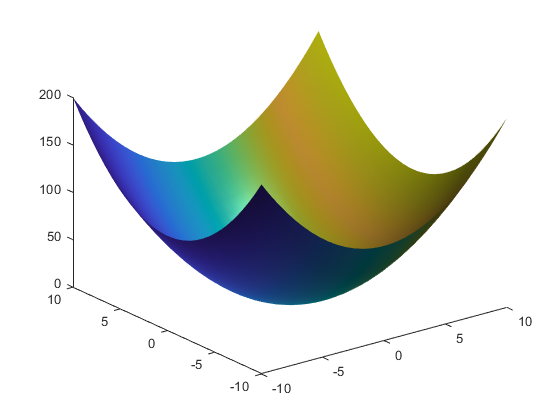

uinterval=[-10,10];
vinterval=[-10,10];

hh.drawmesh(uinterval,vinterval,0);
hold on;
syms t;
u(t)=[0.1+t;0];
 hh.scale=0;
hh.parallel_transport(u,[0;3],[0,1],30);

figure;
hh.Gauss_curvature

$$ans = \frac{4}{{\left(4\,{u_{1}}^{2}+4\,{u_{2}}^{2}+1\right)}^{2}}$$

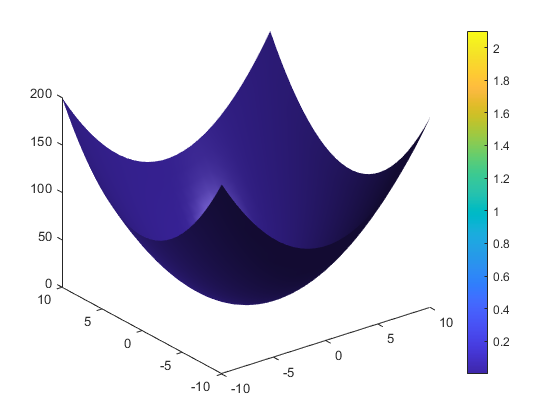

hh.drawmesh(uinterval,vinterval,1);

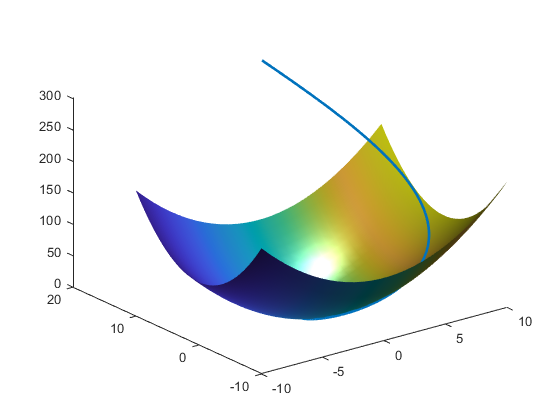

figure;
hh.drawmesh(uinterval,vinterval,0);
hold on;
hh.geodesic([0,3000],[0.1, 0, -0.1, 1],1000);